% The following matrix implements the SIR dynamics example from Chapter 9.3
% of the textbook.
A = [0.95 0.04 0 0; 
    0.05 0.85 0 0; 
    0 0.1 1 0; 
    0 0.01 0 1];

% The following matrix is needed to use the lsim function to simulate the
% system in question
B = zeros(4,1);

% initial conditions (i.e., values of S, I, R, D at t=0).
x0 = [0.9 0.1 0 0];

% Here is a compact way to simulate a linear dynamical system.
% Type 'help ss', 'help lsim', etc., to learn about how these functions work!!
sys_sir_base = ss(A,B,eye(4),zeros(4,1),1);
Y = lsim(sys_sir_base,zeros(1000,1),linspace(0,999,1000),x0);


sirafun = function_handle with value:
    @(x)siroutput(x,t,Y)


sys_sir_base =
 
  A = 
         x1    x2    x3    x4
   x1  0.95     0     0     0
   x2  0.05  0.89     0     0
   x3     0   0.1     1     0
   x4     0  0.01     0     1
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Sample time: 1 seconds
Discrete-time state-space model.

    0.9000    0.1000         0         0
    0.8550    0.1340    0.0100    0.0010
    0.8122    0.1620    0.0234    0.0023
    0.7716    0.1848    0.0396    0.0040
    0.7331    0.2031    0.0581    0.0058
    0.6964    0.2174    0.0784    0.0078
    0.6616    0.2283    0.1001    0.0100
    0.6285    0.2362    0.1230    0.0123
    0.5971    0.2417    0.1466    0.0147
    0.5672    0.2450    0.1707    0.0171
    0.5389    0.2464    0.1952    0.0195
    0.5119    0.2462    0.2199    0.0220
    0.4863    0.2447    0.2445    0.02

cost = 3.9980

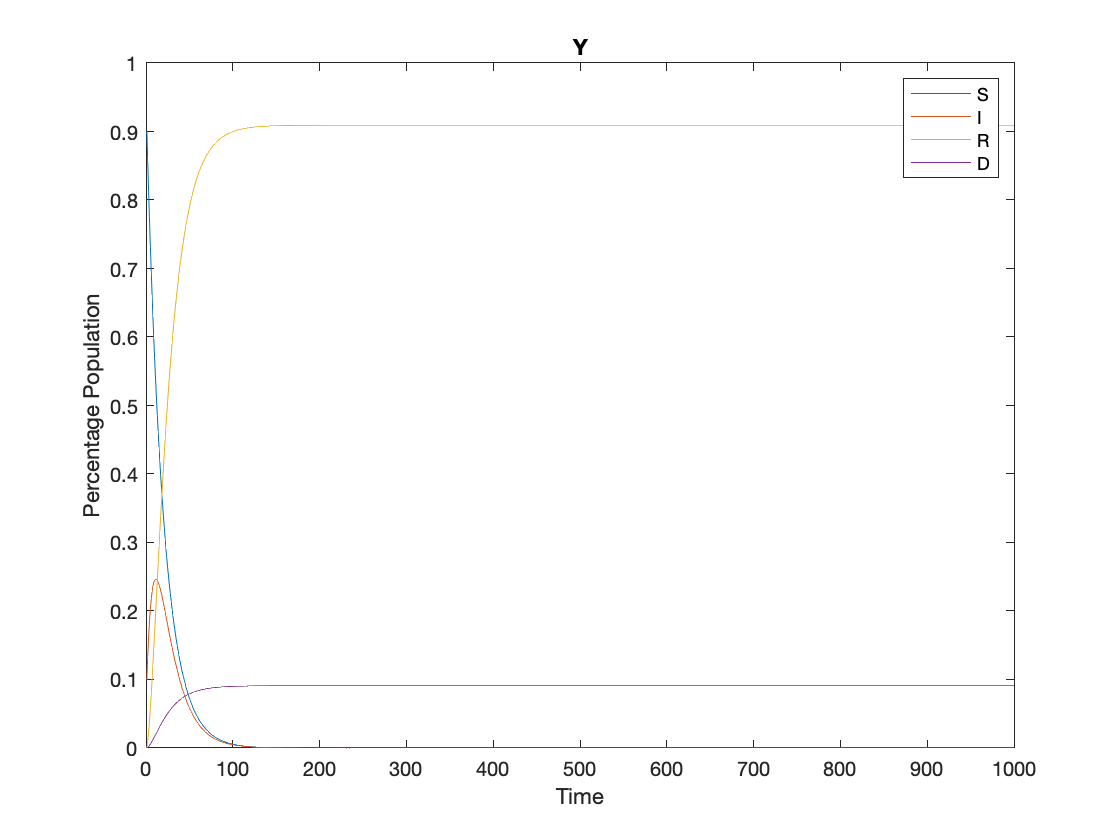


% plot the output trajectory
figure;
plot(Y);
legend('S','I','R','D');
title("Y");
xlabel('Time')
ylabel('Percentage Population');

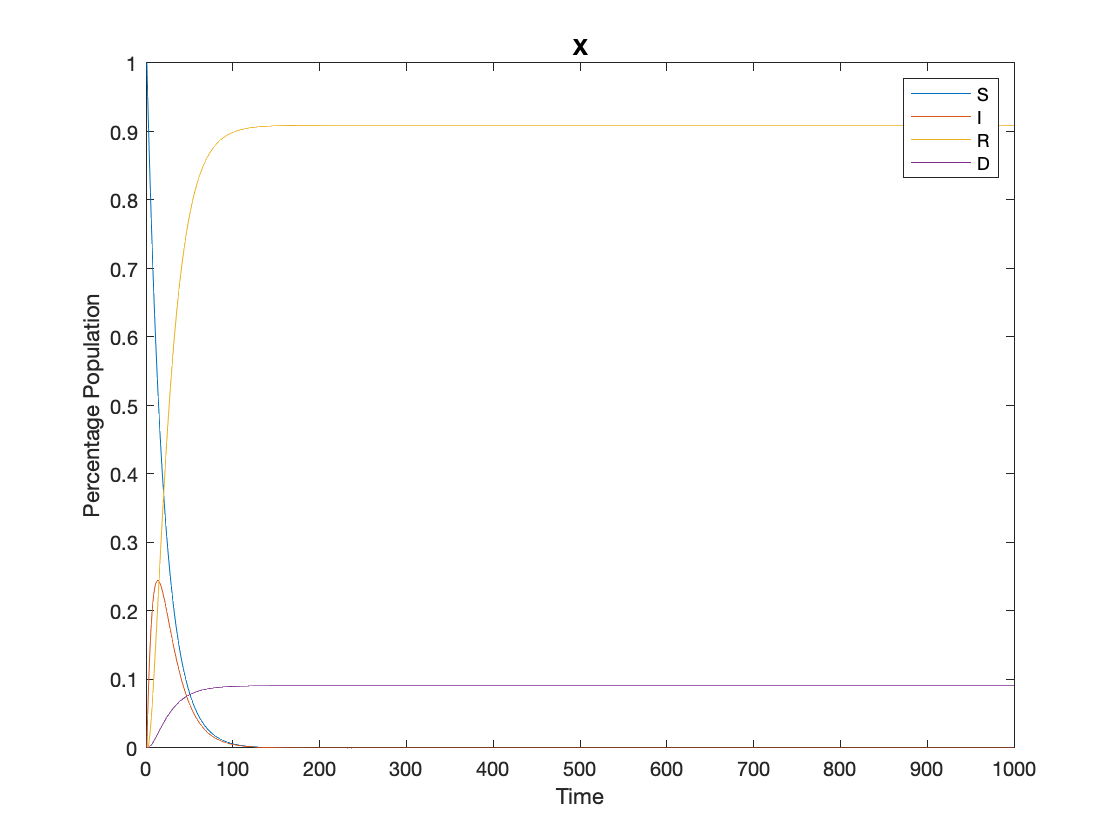

% 2nd way to show data
x = zeros(4, 1000);
x(:,1) = [1; 0; 0; 0];
for i=2:1000
    x(:,i) = A*x(:,i-1);
end
x = x';
%plot the 2nd set
figure;
plot(x);
legend('S','I','R','D');
title("X");
xlabel('Time')
ylabel('Percentage Population');